# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.10 极坐标绘图技巧

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

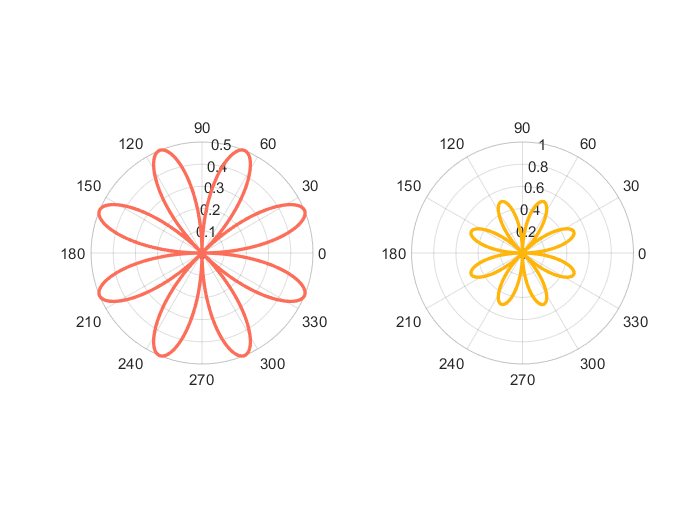

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
figure;
theta = 0:0.01:2*pi;
rho = sin(2*theta).*cos(2*theta);
tiledlayout(1, 2);
nexttile;
polarplot(theta, rho, 'Color', all_colors(1, :), 'LineWidth', 2);
nexttile;
rMax = 2*max(rho);
% 这个看不到线，因为只有一个重复的点
polarplot([0, 2*pi], [rMax, rMax]);    
hold on
polarplot(theta, rho, 'Color', all_colors(2, :), 'LineWidth', 2);
hold off